# Laboratorio 3 - Modelo diferencial de primer orden

Andrés Felipe Medina - Juan Camilo Santana - Osmar Ediber Toloza

[https://github.com/oetolozab/robotica-lab3](https://github.com/oetolozab/robotica-lab3)

## Parte I - Planeación de Trayectoria

En primer lugar, se crea el robot, el cual corresponde al IRB2400 de ABB.

clear
clc
close all

%Parámetros del manipulador - dm
l1=6.15;
l2=1.00;
l3=7.05;
l4=sqrt(1.35^2+7.55^2);
l5=0.85;

%% DH modificado
%Creación del robot
L(1)=Link([0 l1 0 0],'modified');
L(2)=Link([0 0 l2 pi/2],'modified');
L(2).offset=pi/2;
L(3)=Link([0 0 l3 0],'modified');
L(4)=Link([0 7.55 1.35 pi/2],'modified');
L(5)=Link([0 0 0 -pi/2],'modified');
L(6)=Link([0 0 0 pi/2],'modified');

irb2400=SerialLink(L,'name','ABB IRB2400');
irb2400.tool = [eye(3) [0 0 l5]';0 0 0 1];
irb2400

 
irb2400 = 
 
ABB IRB2400 (6 axis, RRRRRR, modDH, fastRNE)                                  
                                                                              
+---+-----------+-----------+-----------+-----------+-----------+             
| j |     theta |         d |         a |     alpha |    offset |             
+---+-----------+-----------+-----------+-----------+-----------+             
|  1|         q1|       6.15|          0|          0|          0|             
|  2|         q2|          0|          1|      1.571|      1.571|             
|  3|         q3|          0|       7.05|          0|          0|             
|  4|         q4|       7.55|       1.35|      1.571|          0|             
|  5|         q5|          0|          0|     -1.571|          0|             
|  6|         q6|          0|          0|      1.571|          0|             
+---+-----------+-----------+-----------+-----------+-----------+             
                                     

Así mismo, se ilustra la configuración *Home*, resaltando las tramas base y del efector final.

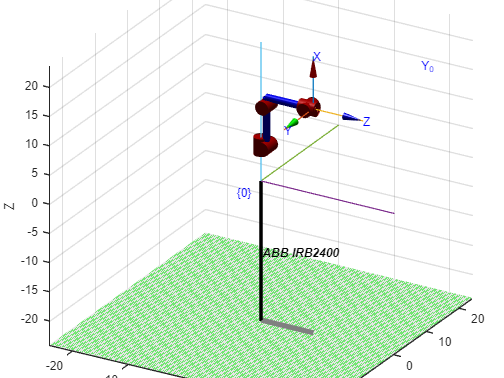

irb2400.plot([0 0 0 0 0 0])
view([30.2 24.8])
axis('auto')
hold on
trplot(eye(3),'frame','{0}','arrow','length','1')
hold off

Posteriormente, se seleccionó como trayectoria a seguir la ilustrada en la figura 1.

*Figura 1. Trayectoria seleccionada.*

Considerando la recomendación de asignar como *L* un valor del 40% del alcance horizontal máximo del robot (1,55 m), se definió esta dimensión como:

ah=15.5; % alcance horizontal máximo (dm)
l=ah*0.4; 

### Creación de trayectoria

Con el fin de asegurar una descripción lo más fiel posible de la trayectoria propuesta, se dividió la misma en un total de 11 tramos. Las ecuaciones de movimiento para cada tramo se diseñaron asumiendo que la trayectoria se encuentra sobre el plano YZ, para facilitar los cálculos. Posteriormente, se realiza la respectiva rotación de los puntos resultantes para ubicarlos en el plano perpendicular al vector $\hat{n}=[1~0~1]$. 

Por último, buscando una uniformidad temporal y una obtención adecuada de la trayectoria, todos los tramos se diseñaron con el mismo intervalo de tiempo *dt.*

**Tramo 1**

Este tramo es de aceleración. Su objetivo es llevar al efector final de una velocidad inicial de cero a una velocidad final de 500 mm/s. Lo anterior se realizó mediante la implementación de la función *poly3*, la cual emplea un polinomio de orden 3 para cumplir las condiciones de frontera $x_0,v_0.x_f,v_f$. A partir de un proceso de ensayo y error, se encontró que una distancia final $x_f$ de 150 mm generaba un perfil de aceleración tolerable por el robot. 

Este tramo se intentó generar con la función *poly5* que emplea polinomios de orden 5; no obstante, para cumplir con las condiciones de aceleración, el polinomio solución generaba un recorrido más allá de la longitud deseada, por lo que se descartó su implementación.

En las condiciones iniciales, los signos negativos indican la dirección hacia la cual se desea que se desplace el efector final.

close all

t_t1 = linspace(0,0.2,5)';
x_t1 = 7.5*ones(length(t_t1),1);
[y_t1,v_t1,a_t1] = poly3([0 0 -1.5 -5],t_t1);
z_t1 = 10*ones(length(t_t1),1);

**Tramo 2**

Este es un tramo de velocidad crucero. En él, el efector final viaja a una velocidad constante de 500 mm/s. Dado que $L=620$ mm, de los cuales ya se han recorrido 150, se decidió asignar como distancia para este tramo $x=110$ mm. Lo anterior con el fin de asegurar que la curva inferior izquierda de la trayectoria (tramo 3) pueda tener un radio de 50 mm.

Nótese que se emplean las ecuaciones de movimiento con velocidad constante para definir este tramo.

v_t2 = -5; %Velocidad crucero
t_t2f = 1.1/abs(v_t2);

dt = t_t1(2)-t_t1(1);
t_t2 = (dt:dt:t_t2f)';

x_t2 = 7.5*ones(length(t_t2),1);
y_t2 = y_t1(length(y_t1)) + v_t2*t_t2;
z_t2 = 10*ones(length(t_t2),1);

**Tramo 3**

Este tramo se diseñó a partir de las ecuaciones de movimiento circular con velocidad angular constante. Se asignó un radio de trayectoria de 50 mm. A partir de la restricción de velocidad crucero, se calculó una velocidad angular $w_{t3}=10~rad/s$. Posteriormente, se calculó el tiempo que debía tardar este tramo, considerando $w_{t3}$ y que se debía recorrer $1/4$ de circunferencia (de $-\pi/2$ a $-\pi$). Finalmente, se obtuvieron las coordenadas $y$ y $z$ de los puntos de la circunferencia contemplados a partir de la expresión $y=y_0+r\cos{\theta}$ y $z=z_0+r\sin{\theta}$.

w_t3 = v_t2/0.5;
t_t3f = abs((-pi+pi/2)/w_t3);

t_t3 = (dt:dt:t_t3f)';

theta_3 = -pi/2+w_t3*t_t3;
x_t3 = 7.5*ones(length(t_t3),1);
y_t3 = y_t2(length(y_t2))+0.5*cos(theta_3);
z_t3 = 10.5+0.5*sin(theta_3);

**Tramo 4**

Este tramo se diseñó de forma idéntica al tramo 2, con la diferencia de que la coordenada $z$ es la que varía en este caso. Su longitud (155 mm) se asignó como $1/4$ del largo $L$ de la trayectoria.

% v_t2 = -5; %Velocidad crucero
v_t4 = -v_t2;
t_t4f = 1.55/v_t4;

% dt = t_t1(2)-t_t1(1);
t_t4 = (dt:dt:t_t4f)';

x_t4 = 7.5*ones(length(t_t4),1);
y_t4 = -3.1*ones(length(t_t4),1);
z_t4 = z_t3(length(z_t3)) + v_t4*t_t4;

**Tramo 5**

Su diseño es idéntico al del tramo 3, aunque la circunferencia en este caso se recorre entre $-\pi$ y $-3\pi/2$.

% w_t3 = v_t2/0.5;
t_t5f = abs((-3*pi/2+pi)/10);

t_t5 = (dt:dt:t_t5f)';

theta_5 = -pi+w_t3*t_t5;
x_t5 = 7.5*ones(length(t_t5),1);
y_t5 = y_t4(length(y_t4))+0.5*(1+cos(theta_5));
z_t5 = z_t4(length(z_t4))+0.5*sin(theta_5);

**Tramo 6**

Tramo de velocidad crucero. Es el más largo de todos, con una distancia a cubrir de 520 mm, puesto que los 100 mm restantes son cubiertos por los cuadrantes de circunferencia de los tramos 5 y 7.

% v_t2 = -5; %Velocidad crucero
v_t6 = -v_t2;
t_t6f = 5.2/v_t6;

% dt = t_t1(2)-t_t1(1);
t_t6 = (dt:dt:t_t6f+dt)';

x_t6 = 7.5*ones(length(t_t6),1);
y_t6 = y_t5(length(y_t5)) + v_t6*t_t6;
z_t6 = z_t5(length(z_t5))*ones(length(t_t6),1);

**Tramo 7**

Su diseño varía, respecto al tramo 5, en que se recorre el cuadrante entre $-3\pi/2$ y $-2\pi$.

% w_t3 = v_t2/0.5;
t_t7f = abs((-2*pi+3*pi/2)/10);

t_t7 = (dt:dt:t_t7f)';

theta_7 = -3*pi/2+w_t3*t_t5;
x_t7 = 7.5*ones(length(t_t5),1);
y_t7 = y_t6(length(y_t6))+0.5*cos(theta_7);
z_t7 = z_t6(length(z_t6))-0.5*(1-sin(theta_7));

**Tramo 8**

Su cálculo es similar al del tramo 4, en donde la diferencia está en que se recorre el tramo derecho de la trayectoria, en sentido descendente.

% v_t2 = -5; %Velocidad crucero
v_t8 = v_t2;
t_t8f = abs(1.55/v_t8);

% dt = t_t1(2)-t_t1(1);
t_t8 = (dt:dt:t_t8f)';

x_t8 = 7.5*ones(length(t_t4),1);
y_t8 = 3.1*ones(length(t_t4),1);
z_t8 = z_t7(length(z_t7)) + v_t8*t_t8;

**Tramo 9**

Para este tramo, el cuadrante se recorre entre $0$ y $-\pi/2$. Su diseño es idéntico al de los demás tramos de cuadrante de circunferencia.

% w_t3 = v_t2/0.5;
t_t9f = abs((-pi/2)/10);

t_t9 = (dt:dt:t_t9f)';

theta_9 = w_t3*t_t9;
x_t9 = 7.5*ones(length(t_t5),1);
y_t9 = y_t8(length(y_t8))-0.5*(1-cos(theta_9));
z_t9 = z_t8(length(z_t8))+0.5*sin(theta_9);

**Tramo 10**

Último tramo de velocidad crucero. Su diseño es idéntico al del tramo 2.

% v_t2 = -5; %Velocidad crucero
v_t10 = v_t2;
t_t10f = abs(1.1/v_t10);

% dt = t_t1(2)-t_t1(1);
t_t10 = (dt:dt:t_t10f)';

x_t10 = 7.5*ones(length(t_t10),1);
y_t10 = y_t9(length(y_t9)) + v_t10*t_t10;
z_t10 = 10*ones(length(t_t10),1);

**Tramo 11**

Tramo final. En este, el efector final desacelera de 500 mm/s hasta el reposo. Al igual que para el tramo 1, se empleó la función *poly3*, utilizando como condiciones de frontera $x_0=1,5;~v_0=-5;~x_f=0;~v_f=0$.

t_t11 = (dt:dt:t_t1(length(t_t1)))';
x_t11 = 7.5*ones(length(t_t11),1);
[y_t11,v_t11,a_t11] = poly3([1.5 -5 0 0],t_t11);
z_t11 = 10*ones(length(t_t11),1);

### Gráfica de trayectoria

Se generó un vector temporal con un intervalo de muestreo *dt*, buscando representar apropiadamente en el tiempo el recorrido de la trayectoria. Así mismo, se fusionaron los vectores $x,~y$ y $z$ obtenidos para cada tramo.

taux = [t_t1;t_t2;t_t3;t_t4;t_t5;t_t6;t_t7;t_t8;t_t9;t_t10;t_t11];

t_tray = (0:dt:dt*(length(taux)-1))';
x_tray = [x_t1;x_t2;x_t3;x_t4;x_t5;x_t6;x_t7;x_t8;x_t9;x_t10;x_t11];
y_tray = [y_t1';y_t2;y_t3;y_t4;y_t5;y_t6;y_t7;y_t8;y_t9;y_t10;y_t11'];
z_tray = [z_t1;z_t2;z_t3;z_t4;z_t5;z_t6;z_t7;z_t8;z_t9;z_t10;z_t11];

Luego, se creo una matriz *path* que contuviese la posición para cada punto de la trayectoria. En este punto, entonces, se realizó la rotación de la trayectoria alrededor de un eje paralelo al eje $y$ que pase por un punto $p_{cent}$. Este punto es el centro de la trayectoria. Dado que el vector normal asignado es $\hat{n}=[1~0~1]$, el ángulo de rotación se asignó como $\theta=-\pi/4$.

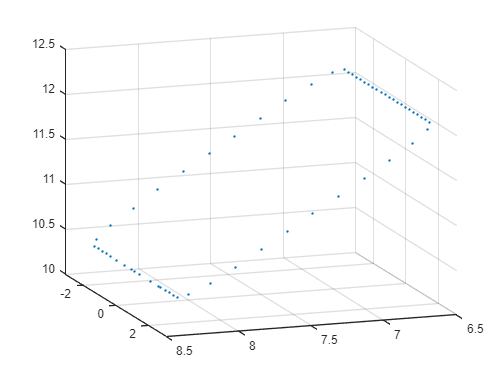

path = [x_tray y_tray z_tray];
p_cent = [7.5 0 (max(z_tray)+min(z_tray))/2];
path_cent = path-repmat(p_cent,size(path,1),1);

R_cent = angvec2r(-pi/4,[0 1 0]);

path = zeros(size(path_cent,1),size(path_cent,2));

figure()

for i = 1:length(path_cent)
    path(i,:) = R_cent*path_cent(i,:)'+p_cent';
end

plot3(path(:,1),path(:,2),path(:,3),'.')
view([160.91 16.41])
axis('auto')
grid on
hold off

### Cinemática inversa y obtención de perfiles para variables de articulación

Con el fin de asegurar que el eje $z$ de la trama del efector final (eje A en la notación NOA) sea normal al plano que contiene la trayectoria, se obtuvo la matriz de rotación $R$ para el robot con la configuración indicada a continuación:

via = zeros(length(path),6);
[R,~] = tr2rt(irb2400.fkine([0 0 pi/4 0 0 0]))

R =    -0.7071   -0.0000    0.7071
    0.0000   -1.0000   -0.0000
    0.7071    0.0000    0.7071


A través de la función *ikinemIRB*, se obtuvo la configuración del robot para cada uno de los puntos que componen la trayectoria, asignando como componente de orientación la matriz $R$ obtenida previamente.

for i = 1:length(path)
    T = [R path(i,:)';0 0 0 1];
    q = ikinemIRB(irb2400,T);
    via(i,:) = q;
end

Se obtuvieron igualmente los perfiles en el tiempo para cada una de las variables $q1,~q2,~q3,~q4,~q5$ y $q6$.

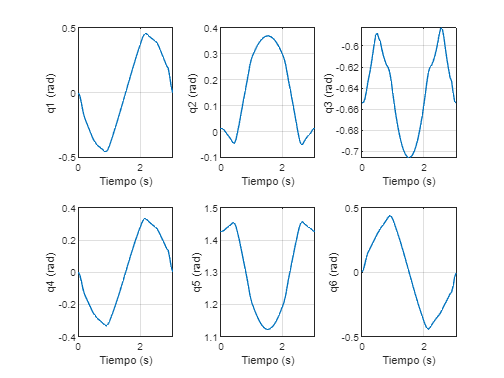

for i = 1:size(via,2)
    num = num2str(i);

    subplot(2,3,i)
    plot(t_tray,via(:,i))
    xlabel('Tiempo (s)')
    ylabel(strcat('q',num,' (rad)'))
    grid on
end

Enseguida, buscando verificar que las velocidades con la que cambiaba cada una de ellas no excedieran las velocidades estipuladas en el catálogo del robot, se empleó la función *diff* para obtener los perfiles de velocidad:

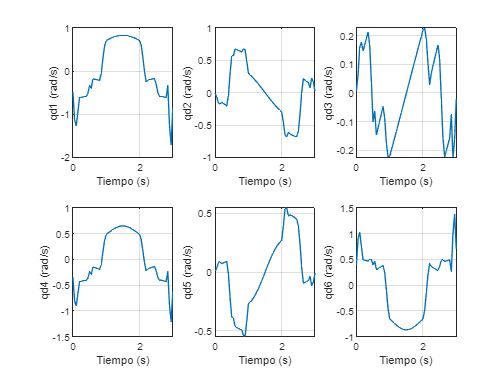

v_via = diff(via,1,1)/dt;

for i = 1:size(v_via,2)
    num = num2str(i);

    subplot(2,3,i)
    plot(t_tray(1:length(t_tray)-1),v_via(:,i))
    xlabel('Tiempo (s)')
    ylabel(strcat('qd',num,' (rad/s)'))
    grid on
end
hold off

Se observó que la máxima velocidad es poco menor a $2~rad/s=114,5917°/s$, la cual es una velocidad menor a las velocidades límite indicadas en el catálogo, en particular, para la articulación 1. Dichas velocidades se encuentran enseguida:

axes_vlim = deg2rad([150 150 150 360 360 450]); % rad/s

Habiéndose obtenido las configuraciones para cada punto, se procedió a implementar el proceso de interpolación mediante la función *mstraj*. Este proceso se realizó a prueba y error, encontrándose que mayores tiempos de aceleración (último parámetro de la función *mstraj*) generaban trayectorias más suaves, pero que tardaban más tiempo en completarse. Por tanto, se asignó un tiempo máximo de aceleración de 0,02 segundos. Más adelante se mostrarán resultados con tiempo más largos.

via_interp = mstraj(via,axes_vlim,[],via(1,:),dt,0.02);
via_interpd = rad2deg(via_interp);
t_tray_interp = (0:dt:dt*(length(via_interp)-1));

A partir de los vectores de configuración obtenidos, se graficaron los nuevos perfiles en el tiempo para cada grado de libertad.

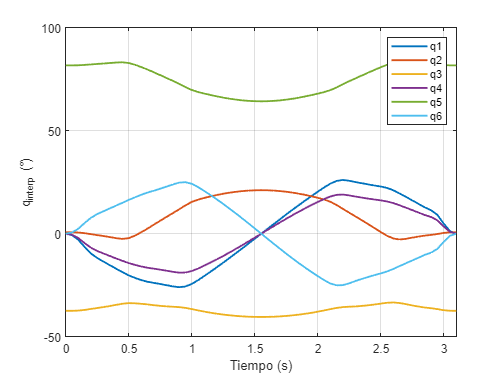

figure()
plot(t_tray_interp,via_interpd(:,1),t_tray_interp,via_interpd(:,2),...
     t_tray_interp,via_interpd(:,3),t_tray_interp,via_interpd(:,4),...
     t_tray_interp,via_interpd(:,5),t_tray_interp,via_interpd(:,6),'LineWidth',1.5);
legend('q1','q2','q3','q4','q5','q6')
xlim([0 t_tray_interp(length(t_tray_interp))])
xlabel('Tiempo (s)')
ylabel('q_{interp} (°)')
grid on

### Verificación de requerimiento en velocidad de recorrido

Ahora, para verificar que la velocidad con la que el robot recorre la trayectoria es la requerida, se empleó la función *diff* para obtener los perfiles de velocidad para la nueva trayectoria en el espacio articular.

v_via_interp = diff(via_interp,1,1)/dt;
v_path = zeros(size(v_via_interp,1),size(v_via_interp,2));

Por otro lado, se calculó el Jacobiano para cada una de las configuraciones involucradas mediante el método *jacob0*, asignando el parámetro *rpy* con el fin de obtener el jacobiano geométrico. A partir de los jacobianos y de los perfiles de velocidad para cada articulación, se obtuvo la velocidad lineal del efector final a partir de la expresión:


$$\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{y} \\
\dot{z} \\
\dot{R} \\
\dot{P} \\
\dot{Y} 
\end{array}\right\rbrack =J\left\lbrack \begin{array}{c}
\dot{q_1 } \\
\dot{q_2 } \\
\dot{q_3 } \\
\dot{q_4 } \\
\dot{q_5 } \\
\dot{q_6 } 
\end{array}\right\rbrack$$


for i = 1:length(v_path)-1
    J = irb2400.jacob0(via_interp(i,:),'rpy');
    v_path(i,:) = J*v_via_interp(i,:)';
end

Finalmente, se graficaron los perfiles de velocidad del efector final en cada eje, así como la velocidad resultante de la suma de cada componente.

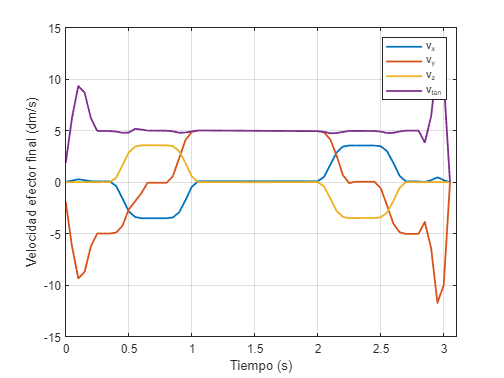

v_t = sqrt(v_path(:,1).^2+v_path(:,2).^2+v_path(:,3).^2);

figure()
plot(t_tray_interp(1:length(t_tray_interp)-1),v_path(:,1),...
     t_tray_interp(1:length(t_tray_interp)-1),v_path(:,2),...
     t_tray_interp(1:length(t_tray_interp)-1),v_path(:,3),...
     t_tray_interp(1:length(t_tray_interp)-1),v_t,'LineWidth',1.5);
legend('v_x','v_y','v_z','v_{tan}')
xlim([0 t_tray_interp(length(t_tray_interp))])
xlabel('Tiempo (s)')
ylabel('Velocidad efector final (dm/s)')
grid on

Nótese que la velocidad requerida de 500 mm/s (5 dm/s) se cumple durante casi toda la trayectoria, excepto en los tramos 1 y 11, los cuales son los tramos de aceleración y desaceleración, como se comentó anteriormente.

### Comparación con segunda interpolación

Al realizar una segunda interpolación con un tiempo máximo de aceleración mayor, se obtuvieron los siguientes resultados:

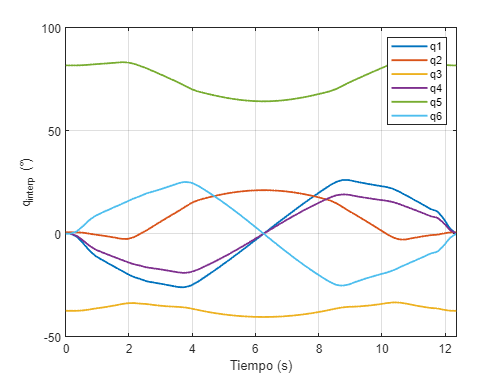

via_interp2 = mstraj(via,axes_vlim,[],via(1,:),dt,0.09);
via_interpd2 = rad2deg(via_interp2);
t_tray_interp2 = (0:dt:dt*(length(via_interp2)-1));

figure()
plot(t_tray_interp2,via_interpd2(:,1),t_tray_interp2,via_interpd2(:,2),...
     t_tray_interp2,via_interpd2(:,3),t_tray_interp2,via_interpd2(:,4),...
     t_tray_interp2,via_interpd2(:,5),t_tray_interp2,via_interpd2(:,6),'LineWidth',1.5);
legend('q1','q2','q3','q4','q5','q6')
xlim([0 t_tray_interp2(length(t_tray_interp2))])
xlabel('Tiempo (s)')
ylabel('q_{interp} (°)')
grid on

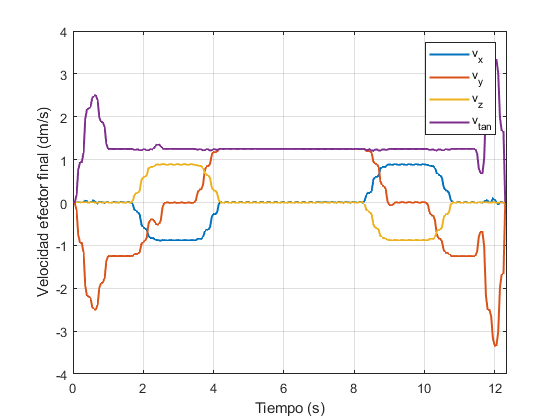


v_via_interp2 = diff(via_interp2,1,1)/dt;
v_path2 = zeros(size(v_via_interp2,1),size(v_via_interp2,2));

for i = 1:length(v_path2)-1
    J = irb2400.jacob0(via_interp2(i,:),'rpy');
    v_path2(i,:) = J*v_via_interp2(i,:)';
end

v_t2 = sqrt(v_path2(:,1).^2+v_path2(:,2).^2+v_path2(:,3).^2);

figure()
plot(t_tray_interp2(1:length(t_tray_interp2)-1),v_path2(:,1),...
     t_tray_interp2(1:length(t_tray_interp2)-1),v_path2(:,2),...
     t_tray_interp2(1:length(t_tray_interp2)-1),v_path2(:,3),...
     t_tray_interp2(1:length(t_tray_interp2)-1),v_t2,'LineWidth',1.5);
legend('v_x','v_y','v_z','v_{tan}')
xlim([0 t_tray_interp2(length(t_tray_interp2))])
xlabel('Tiempo (s)')
ylabel('Velocidad efector final (dm/s)')
grid on

Se observa que los perfiles de posición y velocidad son más suaves, pero el tiempo requerido para completar la trayectoria es ahora de 12,35 segundos. Así mismo, la velocidad crucero es ahora de aproximadamente 125 mm/s, lo cual es de esperarse.

Una solución para obtener un perfil de posición y uno de velocidad más suaves, es iniciar con un muestreo más refinado de la trayectoria durante la definición de los tramos.

## Parte II - Modelo diferencial de primer orden

### Obtención del Jacobiano

Para determinar el jacobiano se empieza por definir las funciones de trasnformación homogéneas entre eslabones a partir de los parámetros de Denavit-Hartenberg, de tal forma que queden en términos de las variables q de cada eslabón. 

syms q1 q2 q3 q4 q5 q6 
MTH_01=MTH(q1, l1, 0, 0);
MTH_12=MTH(q2, 0, l2, pi/2);
MTH_23=MTH(q3, 0, l3, 0);
MTH_34=MTH(q4, 7.55, 1.35, pi/2);
MTH_45=MTH(q5, 0, 0, -pi/2);
MTH_56=MTH(q6, 0, 0, pi/2);
MTH_6T=[eye(3) [0 0 l5]';0 0 0 1];

Se definen las funciones de transferencia homogénea desde cada trama hasta la trama base. 

MTH_02=simplify(MTH_01*MTH_12);
MTH_03=simplify(MTH_01*MTH_12*MTH_23);
MTH_04=simplify(MTH_01*MTH_12*MTH_23*MTH_34);
MTH_05=simplify(MTH_01*MTH_12*MTH_23*MTH_34*MTH_45);
MTH_06=simplify(MTH_01*MTH_12*MTH_23*MTH_34*MTH_45*MTH_56);
MTH_0T=simplify(MTH_01*MTH_12*MTH_23*MTH_34*MTH_45*MTH_56*MTH_6T);

Recordando que el Jacobiano se compone por la componente de velocidad lineal y angular se crean las dos matrices para trabajarlas separadamente por ahora. 


%%
Jacobiano=sym('a',[6 6]);
J_p=sym('a',[3 6]);
J_w=sym('a',[3 6]);

Para encontrar la parte del Jacobiano asociada a la velocidad lineal primero se encuentra la función de la posición dependiente de los valores q de cada eslabón. Luego, se deriva parcialmente con respecto a cada variable para encontrar los coeficientes. Los coeficientes son

pos_x=MTH_0T(1,4);
pos_y=MTH_0T(2,4);
pos_z=MTH_0T(3,4);
pos=[pos_x,pos_y,pos_z];
qs=[q1,q2,q3,q4,q5,q6];

for i=1:3
    for j=1:6
        fprintf("Coeficiente del Jacobiano %d,%d",i,j);
        J_p(i,j)=vpa(simsyms(vpa(diff(pos(i),qs(j)))),2)
    end
end

Luego, se encuentran los coeficientes asociados a la velocidad angular. Para ello se trasladoron todas los ejes de rotación al origen. 

J_w(1:3,1)=vpa(VelAngIndi(MTH_01),2);
J_w(1:3,2)=vpa(VelAngIndi(MTH_02),2);
J_w(1:3,3)=vpa(VelAngIndi(MTH_03),2);
J_w(1:3,4)=vpa(VelAngIndi(MTH_04),2);
J_w(1:3,5)=vpa(VelAngIndi(MTH_05),2);
J_w(1:3,6)=vpa(VelAngIndi(MTH_06),2);

for i=1:3
    for j=1:6
        fprintf("Coeficiente del Jacobiano %d,%d",i+3,j);
        J_w(i,j)=vpa(simsyms(J_w(i,j)),2);
    end
end

El Jacobiano completo es

jacobiano=[J_p;J_w]

La postura seleccionada es q=[100,80,35,100,50,200], valores que permiten que el robot se encuentre en el espacio diestro de trabajo. 

q_nuevos=deg2rad([100,80,35,100,50,200]);
q1=q_nuevos(1);
q2=q_nuevos(2);
q3=q_nuevos(3);
q4=q_nuevos(4);
q5=q_nuevos(5);
q6=q_nuevos(6);

Se evalúa el Jacobiano en dichos valores y se despeja de la ecuación. Lo que equivale a multiplicar por la izquierda por la inversa del Jacobiano para encontrar así las velocidades articulares. 

jacobiano_num=vpa(subs(jacobiano),2);
q_articulares=simplify(rad2deg(inv(jacobiano_num)*[10;20;5;5;10;-5])) %cm/s y rad/s

$$q\_articulares = \left(\begin{array}{c} -63.642417073416964338132262517075\\ -254.67936302690579306768345651229\\ 369.63018536814960091842732458882\\ 90.654621987184283376942899113997\\ 366.72021040205036522294799160725\\ 437.8928170014876353463647429452 \end{array}\right)$$

## Parte III - Integración

Luego de implementar el código en la GUI, se presenta el siguiente resultado:

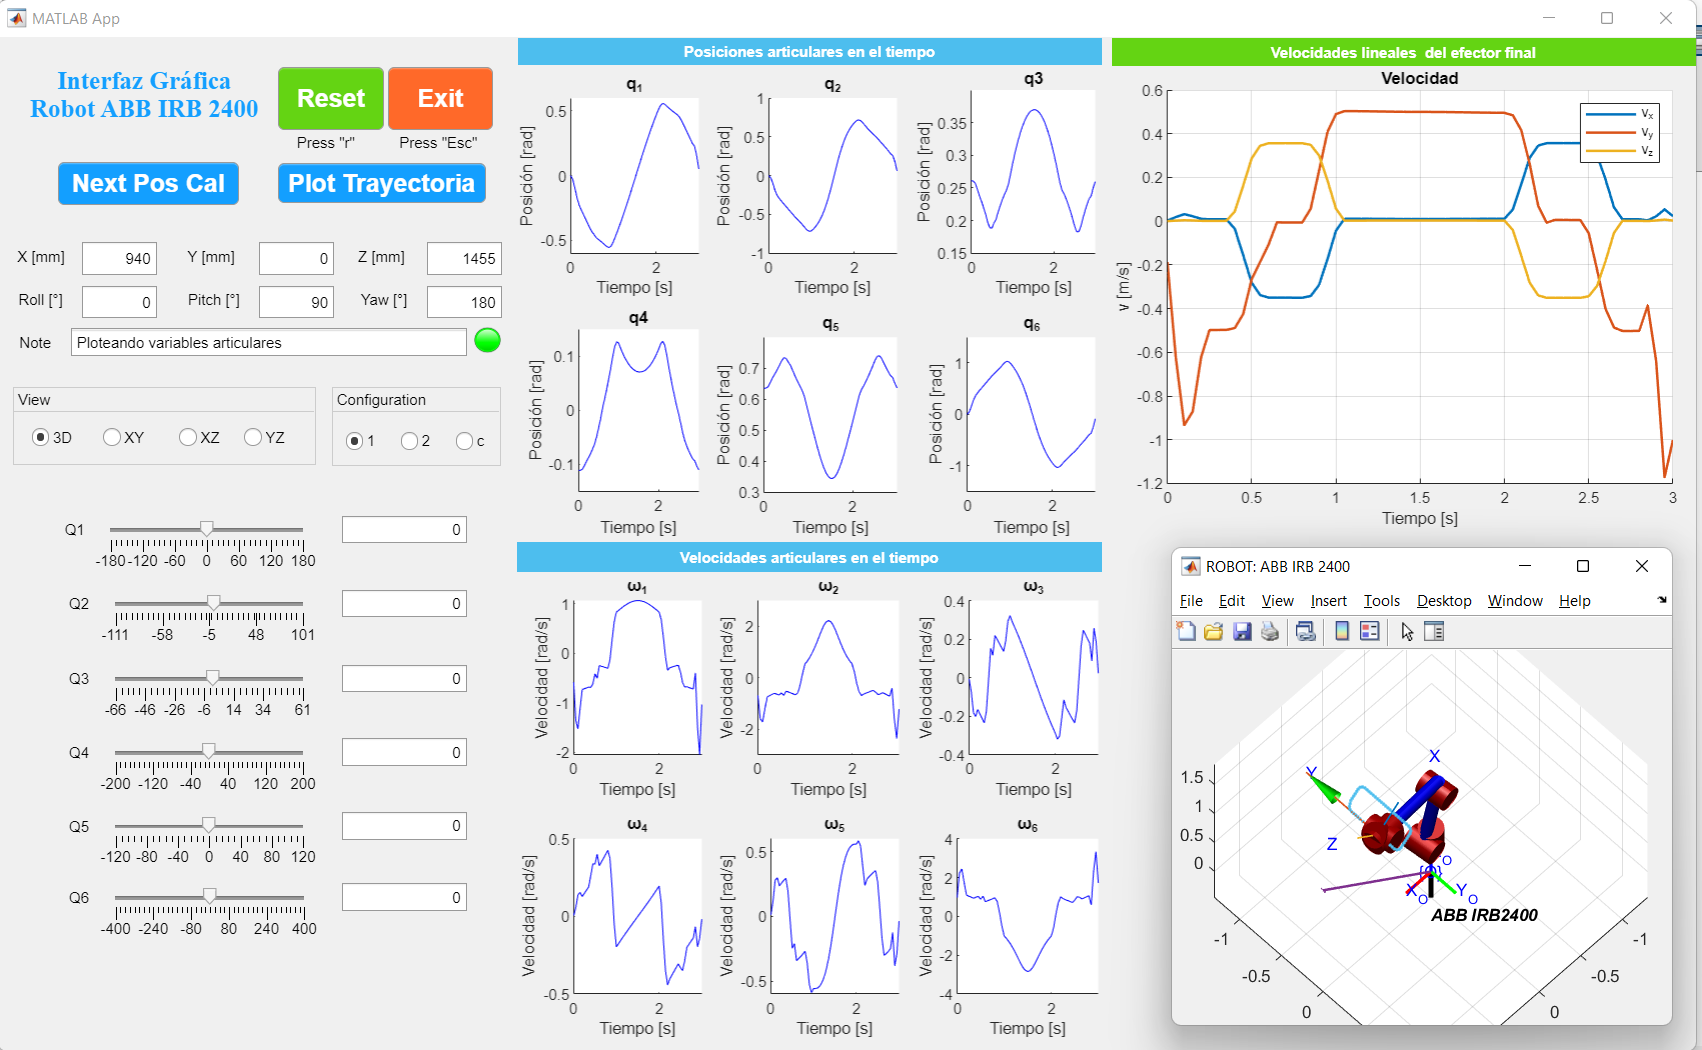

Donde se incorporan las gráficas de los valores de posición ariculares (conjunto de graficas de la mitad superior), las velocidades de éstas (conjunto de velocidades de la mitad inferior), como también la velocidades lineales del efector final (superior derecha), donde al ejecutar la GUI, dinámicamente se grafican los valores, lo cual se evidencia en las siguientes gráficas:

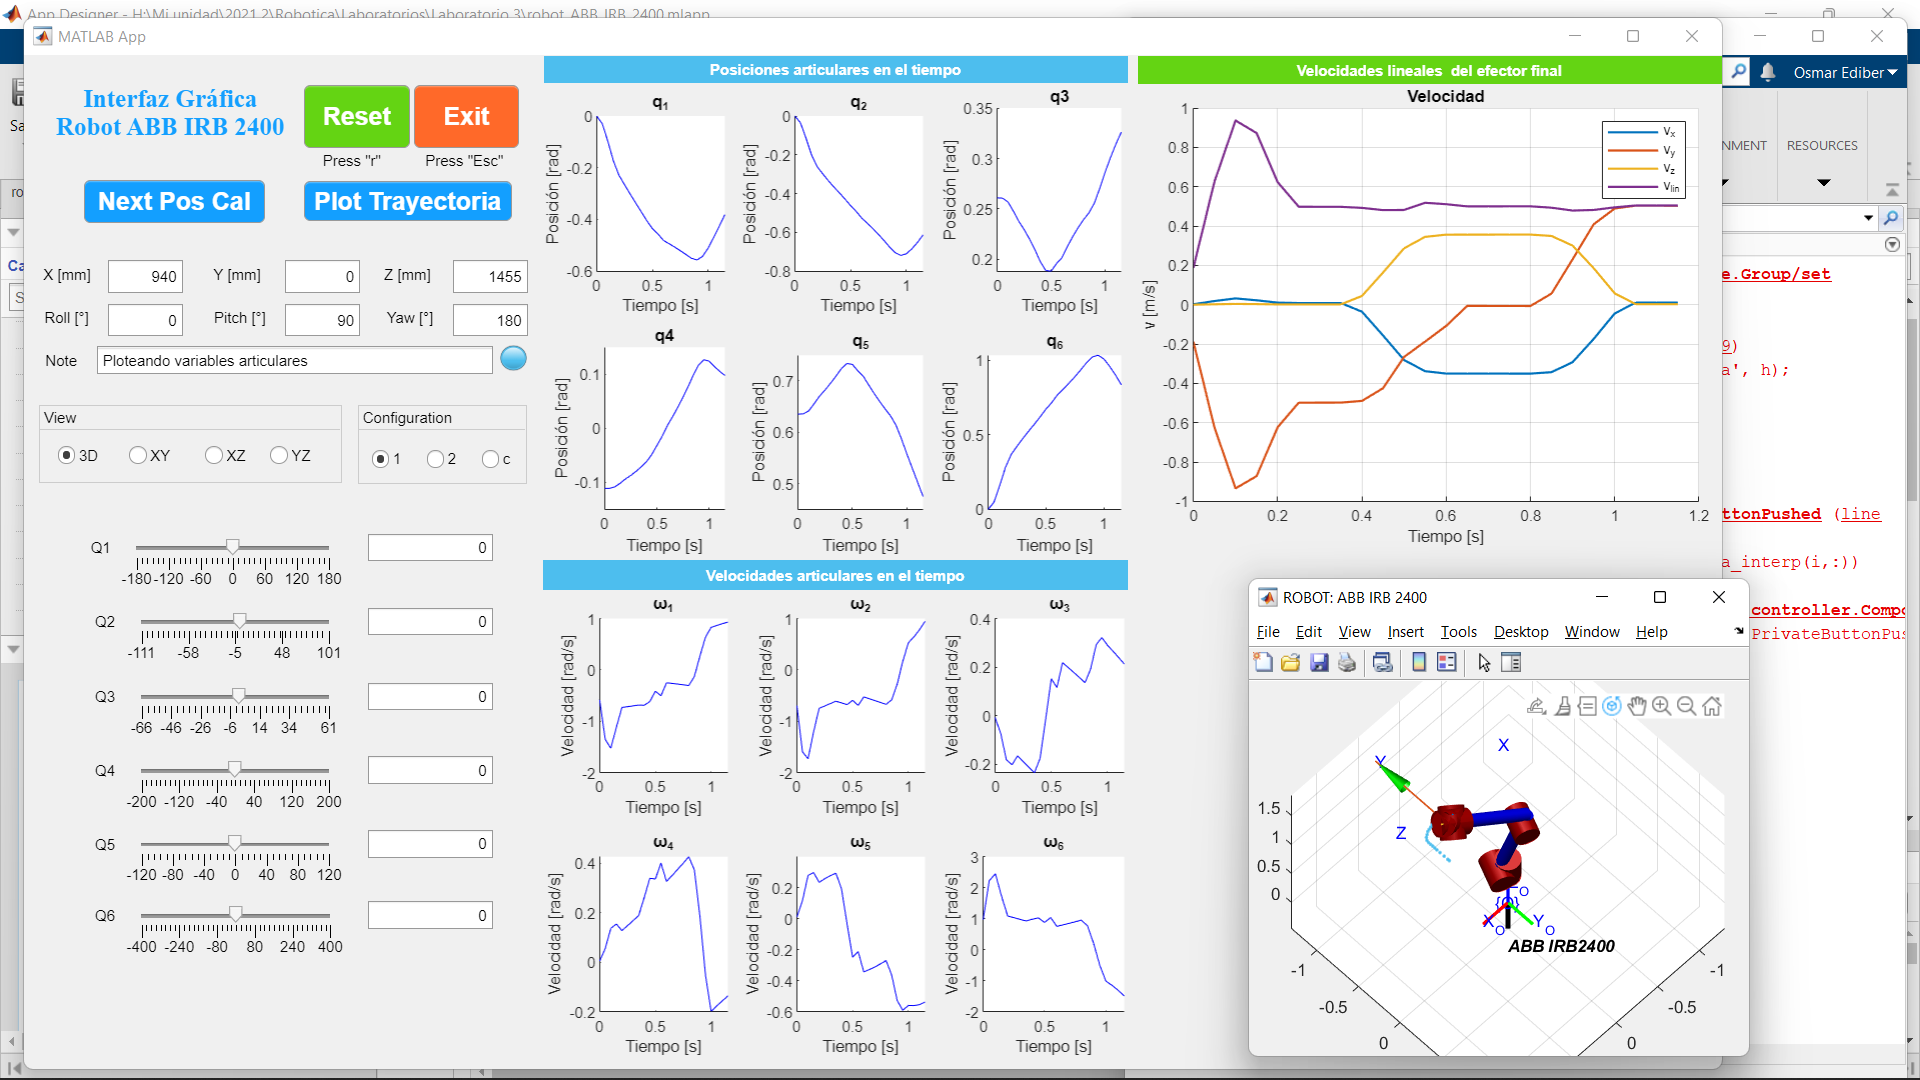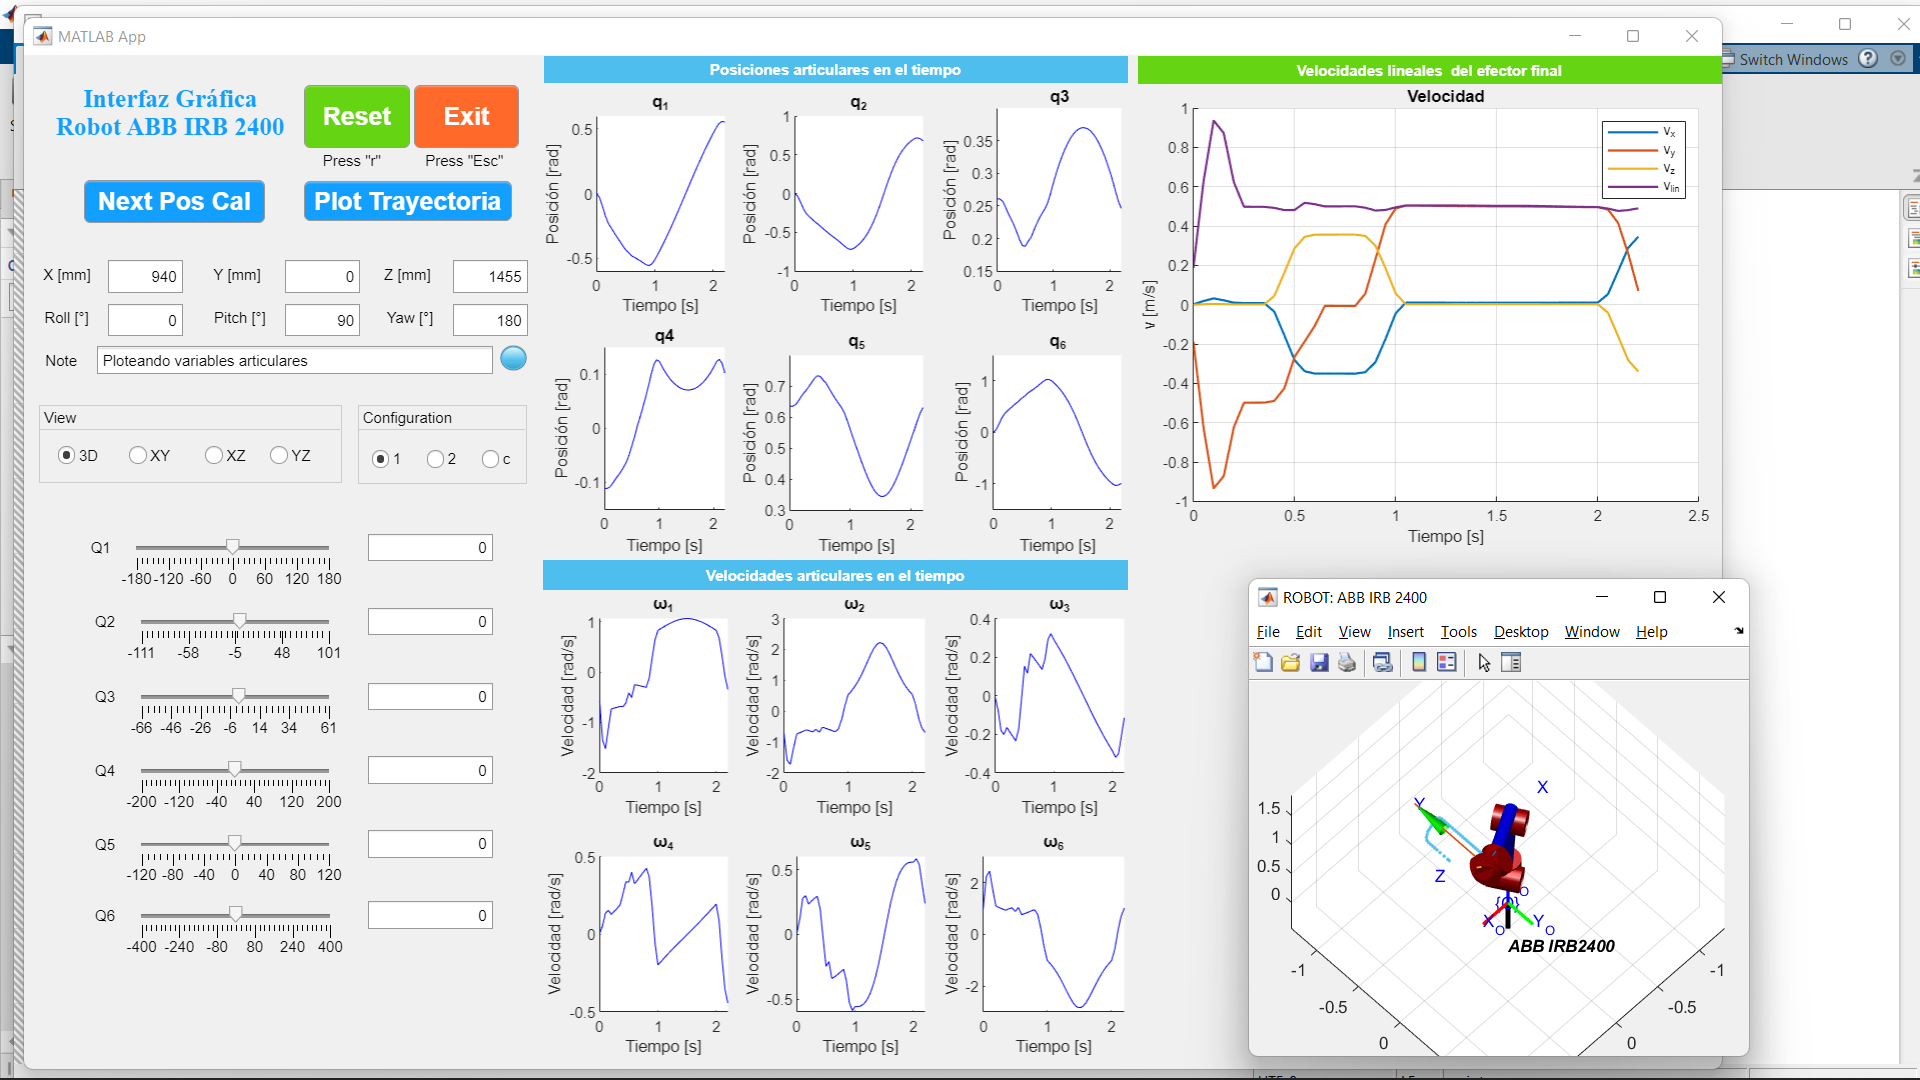

De acuerdo con el código planteado anteriormente, se mapea para que desde la GUI, se realize el ploteo de la información requerida, donde en la siguiente figura se observa la trayectoria, que es perpendicular al vector en cuestión, como se definió anteriormente, es necesario que el centro de la trayectoria se encuentre e 0.75 metros en la dirección z, es por ello que se ve desfasado, a continuación se presenta la vista perspectiva con el vector:

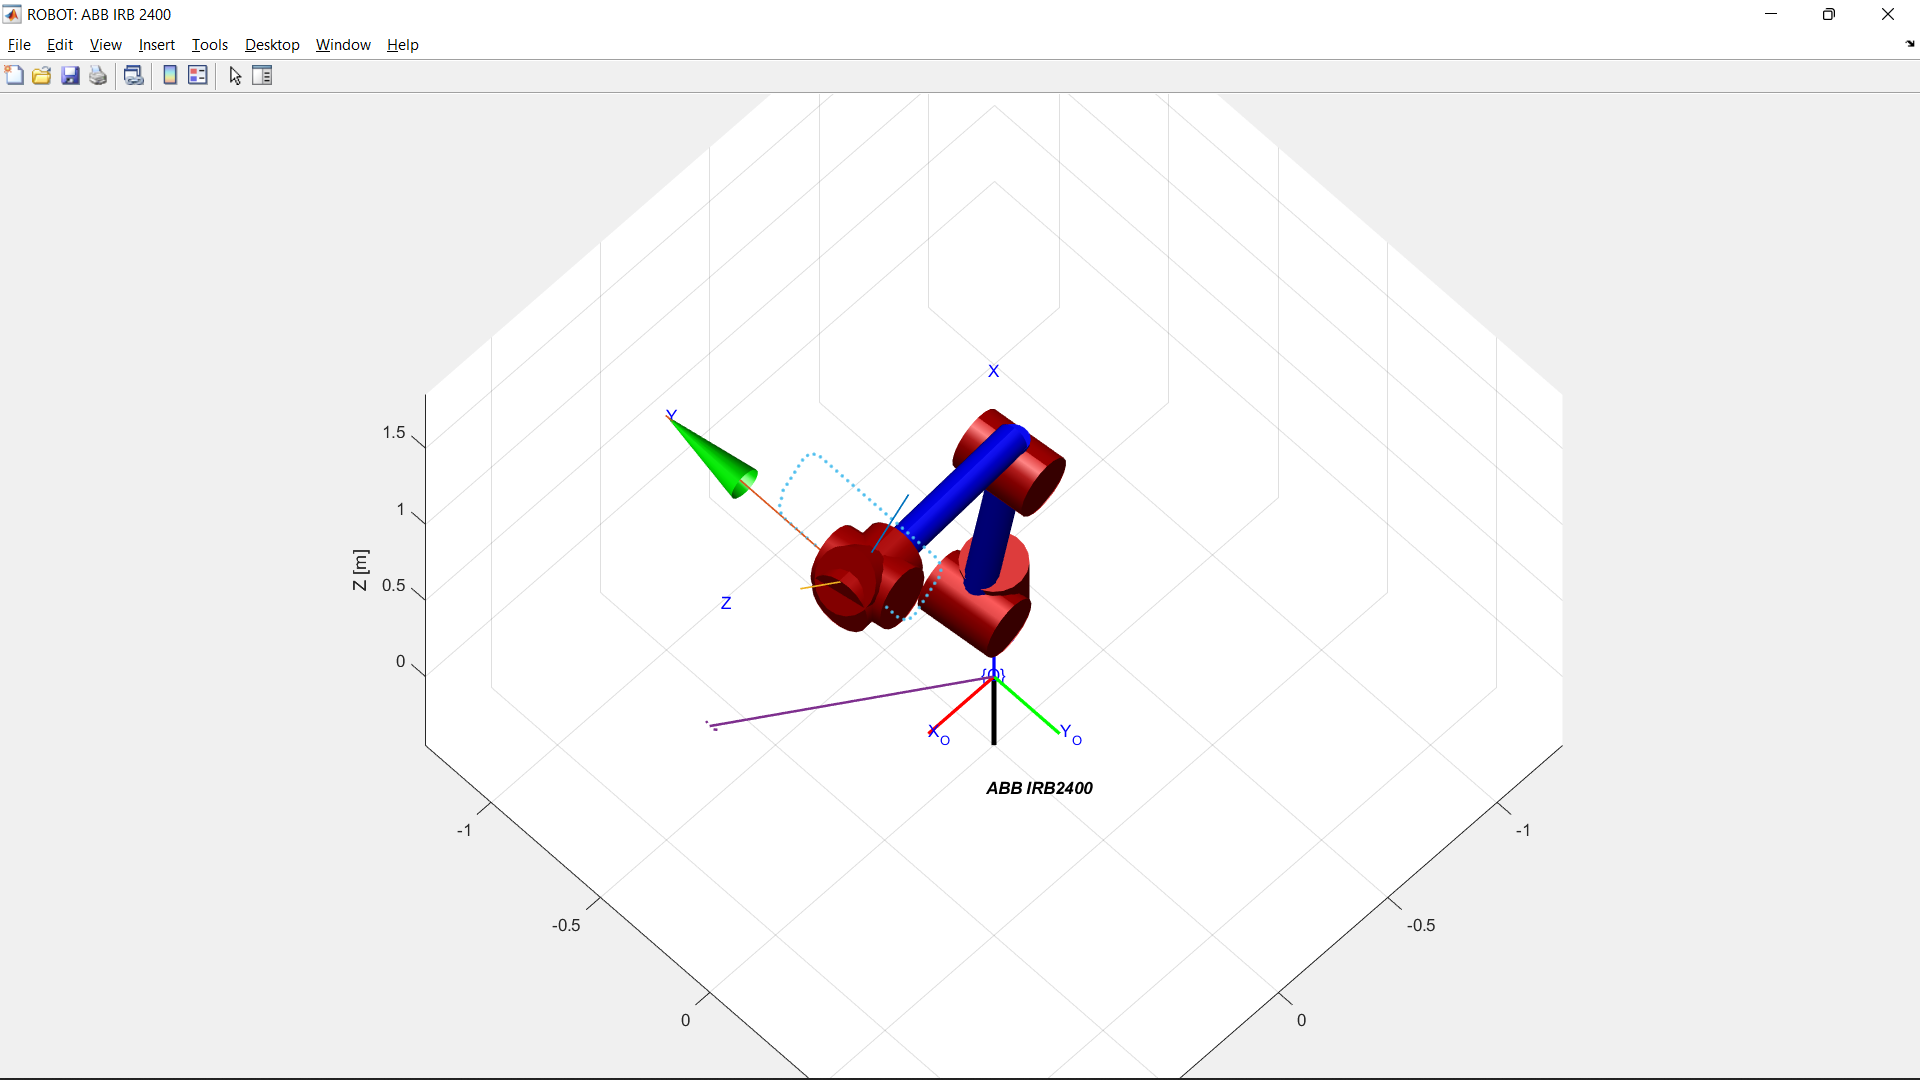

Viéndola desde en el plano z-x se tiene: 

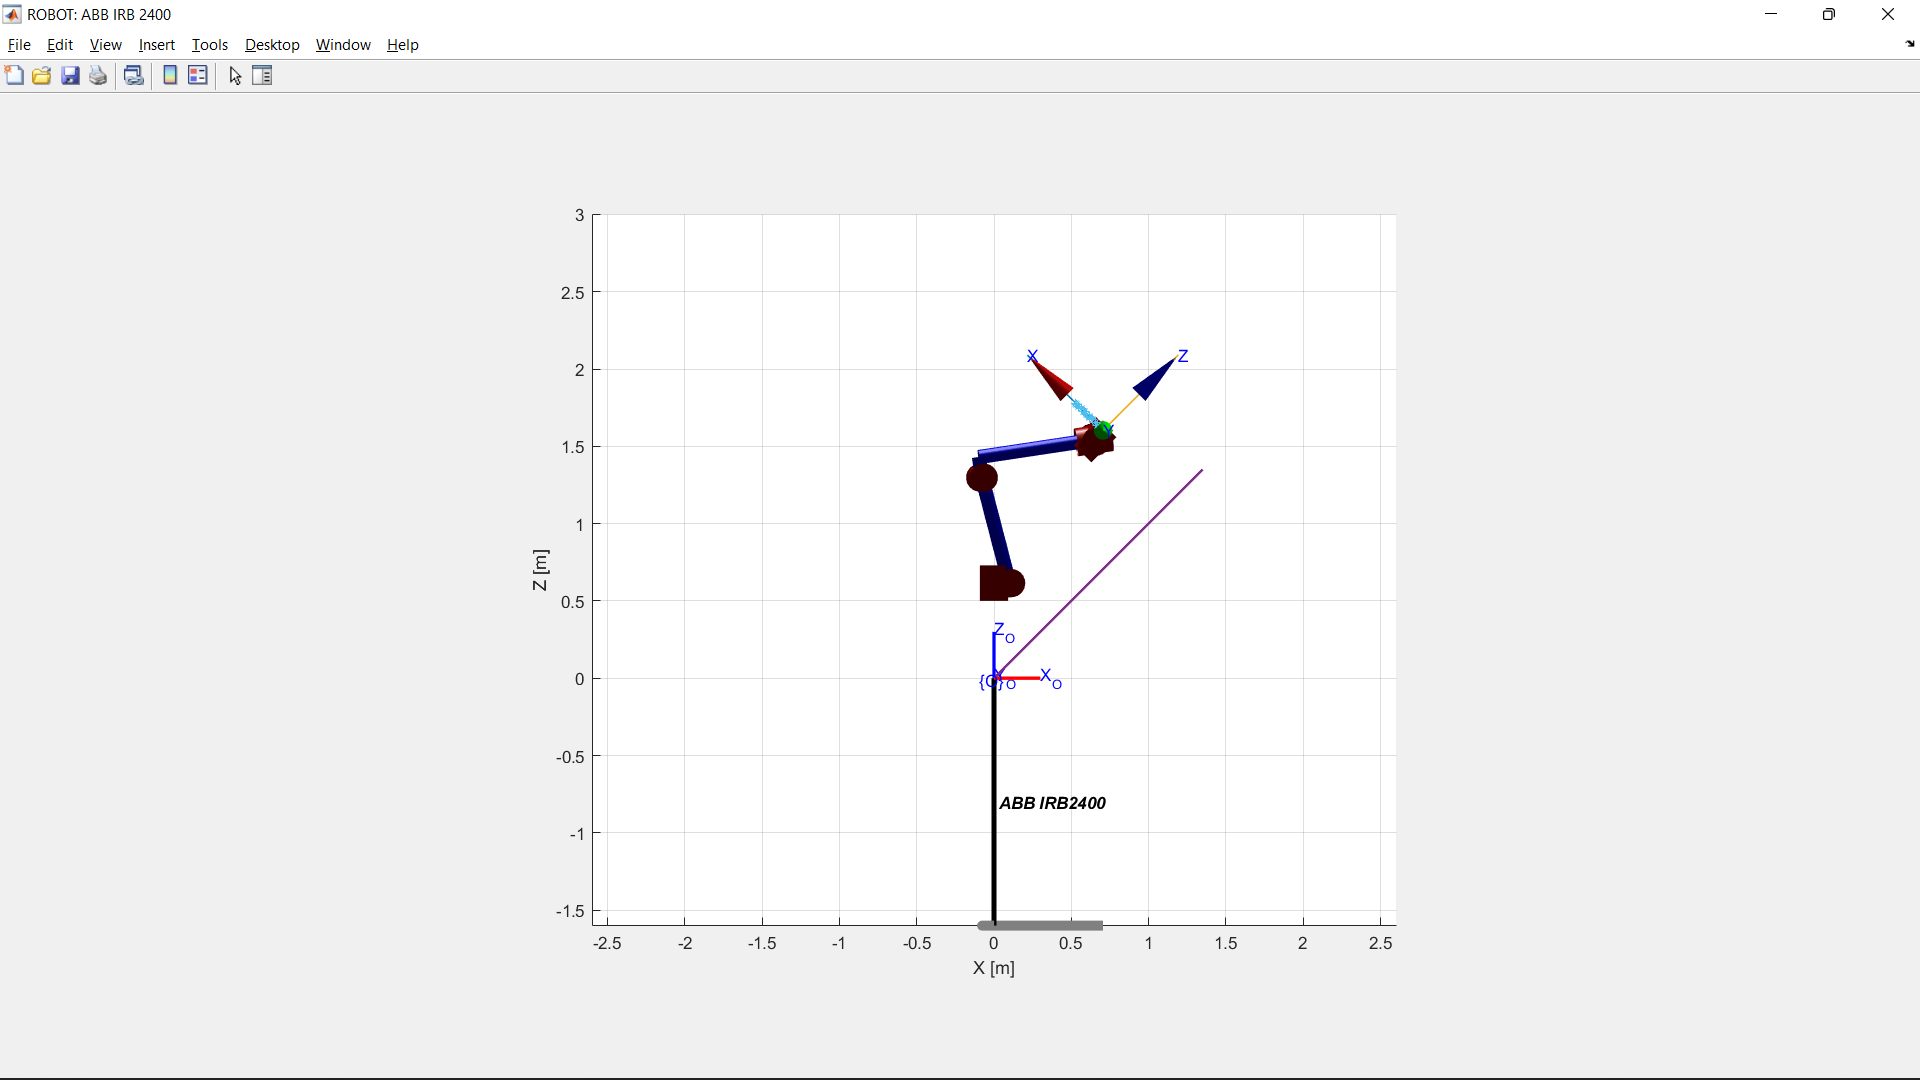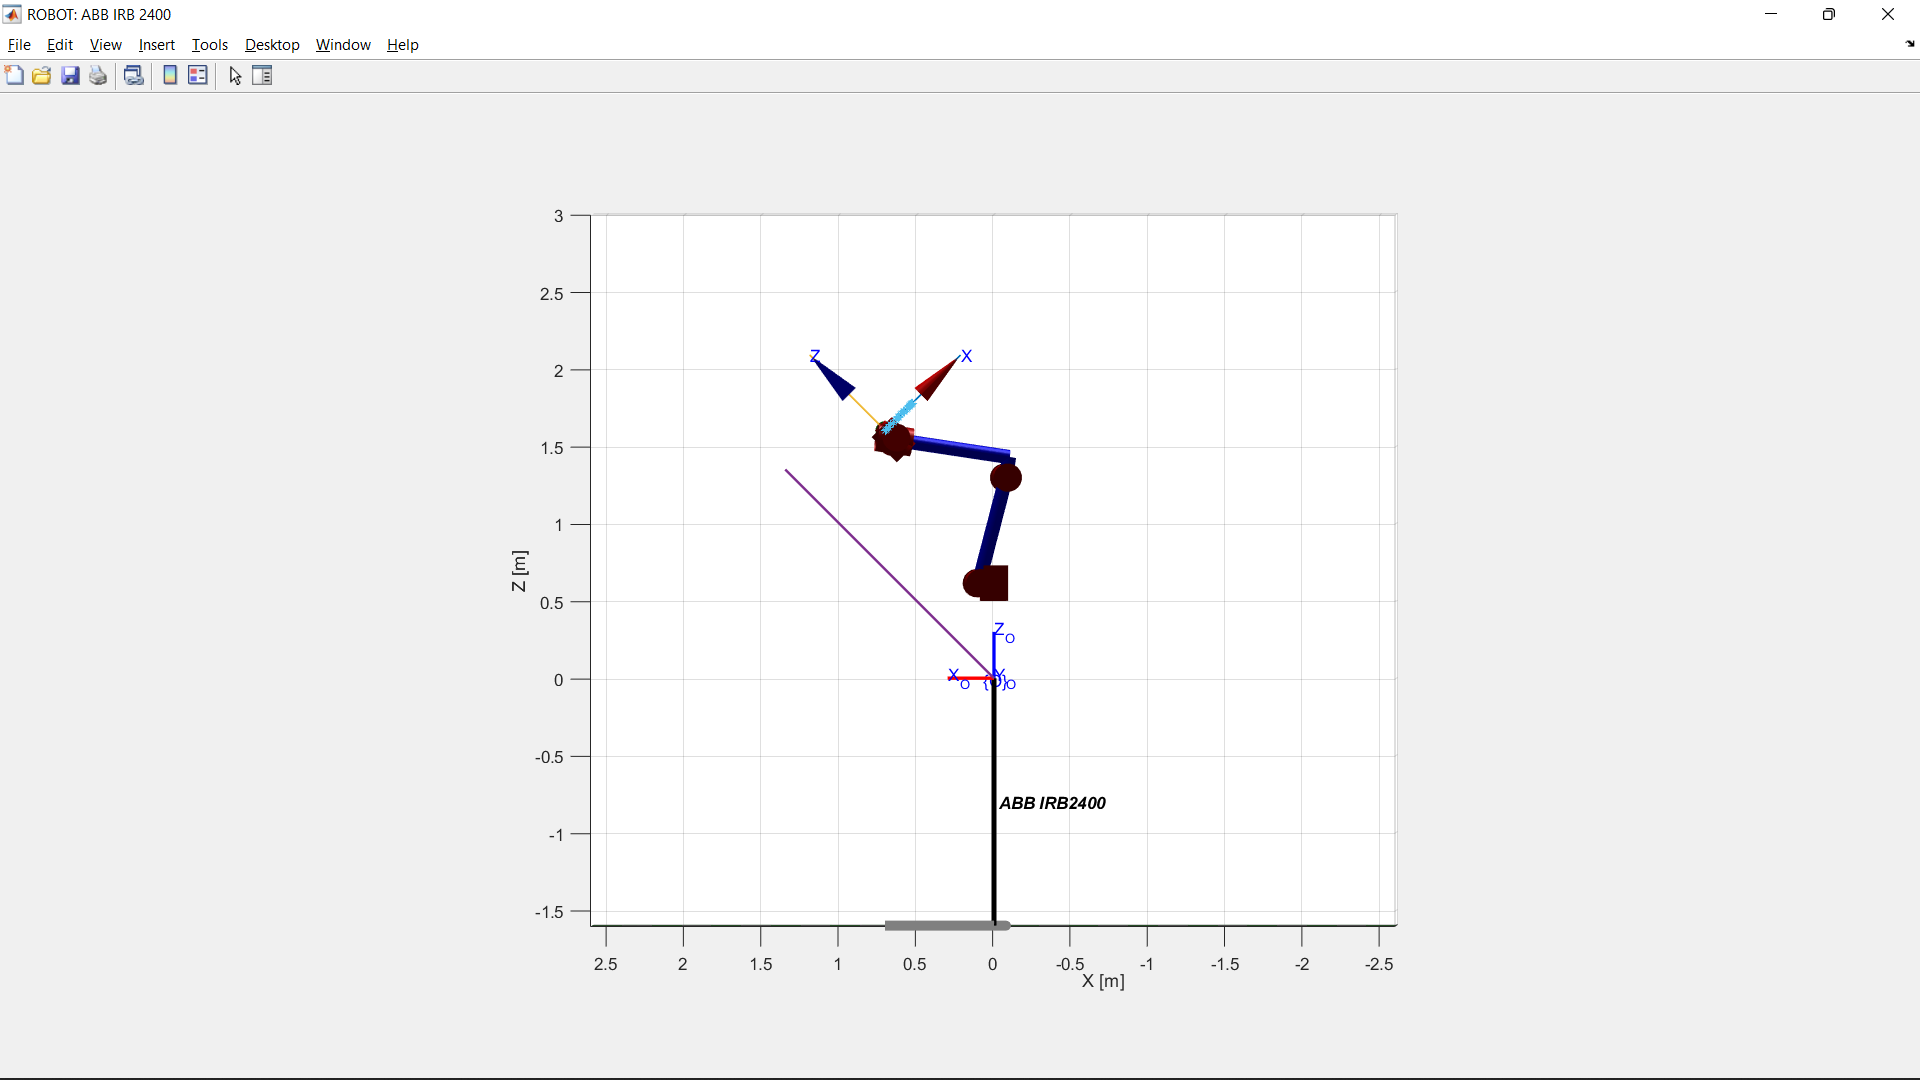

Se evidencia que el eje z se mantiene perpendicular al plano de la trayectoria, ahora considerando el plano ZY, donde se puede notar que el la longitud L de la trayectoria es los 0.62 m, es decir:

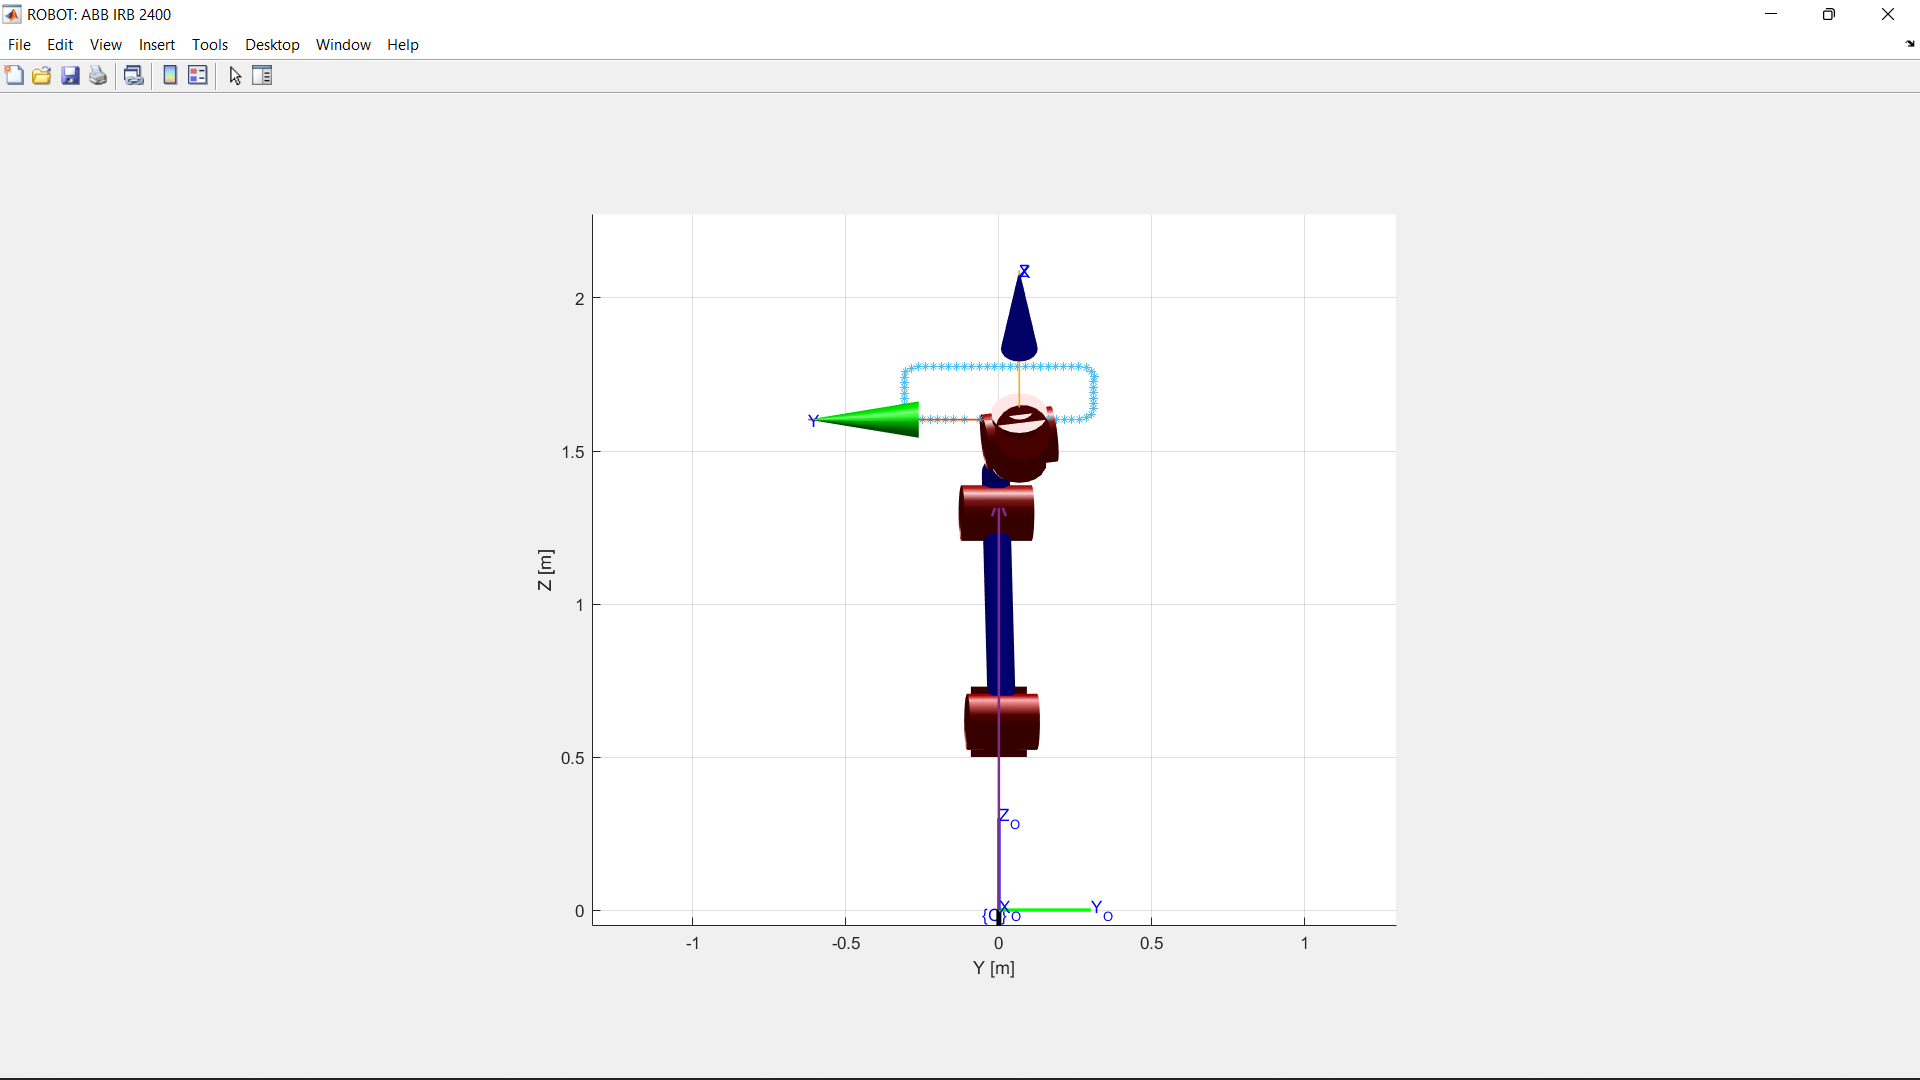

Ahora considerando la velocidad del efector, se evidencia que al obtener la norma de las velocidades $v_x$ (azul), $v_y$ (rojo) y $v_z$ (naranja), se obtiene la velocidad total del efector final (morado), la cual se mantiene en promedio muy cerca a los 500mm/s, que de acuerdo con la gráfica corresponde a los 0.5m/s, nótese que en los picos de los extremos en la velocidad total del efector final, corresponde la aceleración de desaceleración del efector final al inicio y al final de la trayectoria.

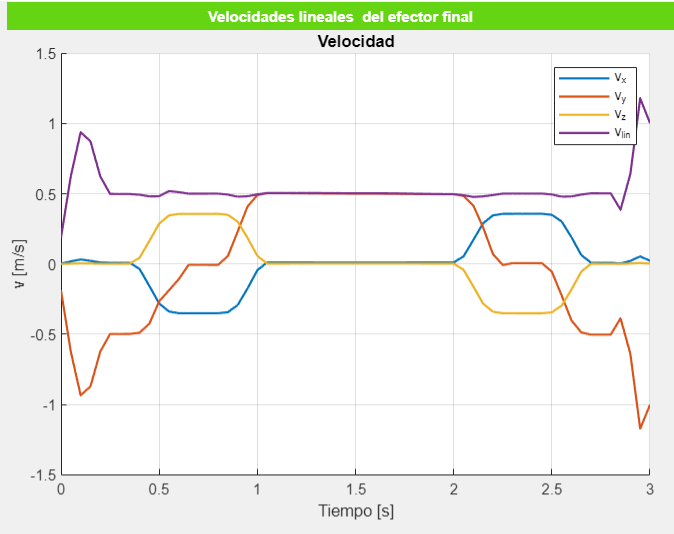

En cuanto al desarrollo de las articulaciones ($q_i$), se evidencia que siguen trayectorias suavizadas, lo cual corresponde con los perfiles para las velocidades articulares (${\textrm{dq}}_i$), donde se evidencia que se mantienen acotadas sin picos repentinos extremadamente grandes.